## 5.

## (a)

function A = FormMatrix(u, alpha)

    beta = 1e-6;
    n = size(u, 1);
    m = sqrt(n);
    v = reshape(u,[m,m])';
    h = 1/(1+m); 

    aw = zeros(m);
    ae = zeros(m);
    as = zeros(m);
    an = zeros(m);
    ac = zeros(m);

    function s = get(i ,j)
        if (i>m || i<1 || j>m || j<1)
            s = 0;
        else
            s = v(i ,j);
        end
    end

    function s = calc(v1,v2,v3,v4)
        s = 1/(2*sqrt(((v1-v2)/h)^2+((v3-v4)/h)^2+beta));
    end

    for i = 1:m
        for j = 1:m
            aw(i,j) = (-alpha/h^2)*(calc(get(i,j), get(i-1,j), get(i,j), get(i,j-1))+...
                calc(get(i,j), get(i-1,j), get(i-1,j+1), get(i-1,j)));
            ae(i,j) = (-alpha/h^2)*(calc(get(i+1,j), get(i,j), get(i+1,j), get(i+1,j-1))+...
                calc(get(i+1,j), get(i,j), get(i,j+1), get(i,j)));
            as(i,j) = (-alpha/h^2)*(calc(get(i,j), get(i-1,j), get(i,j), get(i,j-1))+...
                calc(get(i+1,j-1), get(i,j-1), get(i,j), get(i,j-1)));
            an(i,j) = (-alpha/h^2)*(calc(get(i+1,j), get(i,j), get(i,j+1), get(i,j))+...
                calc(get(i,j+1), get(i-1,j+1), get(i,j+1), get(i,j)));
            ac(i,j) = -(aw(i,j)+ae(i,j)+as(i,j)+an(i,j))+1;
        end
    end

    wcol = reshape(aw(2:m,:)',[],1);
    ecol = reshape(ae(1:m-1,:)',[],1);
    scol = reshape(as',[],1);
    ncol = reshape(an',[],1);
    ccol = reshape(ac',[],1);
    A = sparse(diag(wcol,-m)+diag(ecol,m)+diag(scol(2:n),-1)+diag(ncol(1:n-1),1)+diag(ccol));
end


function u0 = FormRHS(X)
    u0 = reshape(X',[],1);
end

## **(b)**

function [x,iter] = Jacobi(A,b,x_initial,maxiter,tol)
    D = diag(diag(A));
    x = x_initial;
    for iter = 0:maxiter
        r = b - A*x;
        if (norm(r)<=tol*norm(b))
            break
        end
        x = x + D^(-1)*r;
    end
end

function [x,iter] = GS(A,b,x_initial,maxiter,tol)
    D = diag(diag(A));
    L = tril(A);
    x = x_initial;
    for iter = 0:maxiter
        r = b - A*x;
        if (norm(r)<=tol*norm(b))
            break
        end
        x = x + (D+L) \ r;
    end
end


function [x,iter] = SOR(omega,A,b,x_initial,maxiter,tol)
    D = diag(diag(A)/omega);
    L = tril(A);
    x = x_initial;
    for iter = 0:maxiter
        r = b - A*x;
        if (norm(r)<=tol*norm(b))
            break
        end
        x = x + (D+L) \ r;
    end
end


function [x,iter] = CG(A,b,x_initial,maxiter,tol)
    x = x_initial;
    r = b - A*x;
    p = r;
    rnew = r'*r;
    for iter = 0:maxiter
        if (norm(r)<=tol*norm(b))
            break
        end
        alpha = rnew / (p'*A*p);
        x = x + alpha * p;
        r = r - alpha * A * p;
        rold = rnew;
        rnew = r' * r;
        beta = rnew / rold;
        p = r + beta * p;
    end
end


## (c)

#### Find the best omega value for each image size:

function [] = findBest()
    tol = 1e-2;
    trial = 1:100;
    maxiter = 20000;
    k=8;

    size = [16, 32, 64, 128];
    alpha = [6.4e-2, 3.2e-2, 1.6e-2, 8e-3];

    for i=1:4
        m = size(i);
        a = alpha(i);
        bestOmega = 0;
        besttime = 1e8;
        bestiter=1e8;
        [~,z]=set_image(m);
        u0=FormRHS(z);
        for t=trial
            x=u0;
            totaliter=0;
            tic
            for j=1:k
                A=FormMatrix(u0,a);
                [x,iter] = SOR(t,A,u0,x,maxiter,tol);
                totaliter = totaliter+iter;
            end
            time = toc;
            if (totaliter<=bestiter && time<besttime)
                bestiter = totaliter;
                besttime = time;
                bestOmega = t;
            end
        end
        fprintf("grid size is: %d\r\n", m);
        fprintf("total time is: %d\r\n", besttime);
        fprintf("best omega is: %d\r\n\r\n", bestOmega);
    end
end


#### **The best omega values are**:

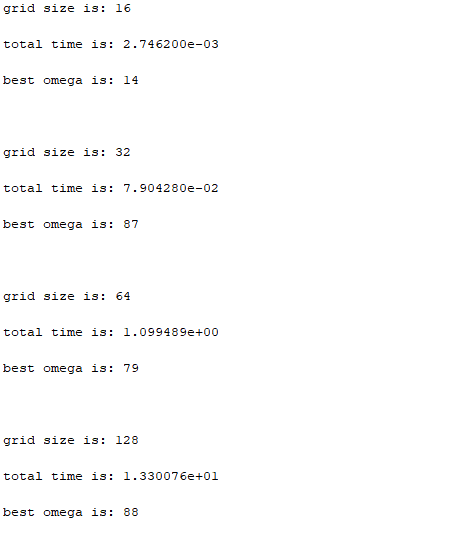

#### The denoise function is:

function [] = denoise()
    tol=1e-2;
    maxiter=20000;
    k=8;
    size = [16,32,64,128];
    alpha = [6.4e-2, 3.2e-2, 1.6e-2, 8e-3];
    omega = [14, 87, 79, 88];
    image_size = zeros(16,1);
    method = strings(16,1);
    times = zeros(16,1);
    iterations = zeros(16,1);

    for i=1:4
        m = size(i);
        a = alpha(i);
        o = omega(i);
        [~,z]=set_image(m);
        u0 = FormRHS(z);
        iterjacobi = 0;
        itergs = 0;
        itersor = 0;
        itercg = 0;
        x_j = u0;
        x_g = u0;
        x_s = u0;
        x_c = u0;

        method((i-1)*4+1)="jacobi";
        image_size((i-1)*4+1)=m;
        tic
        for j=1:k
            A = FormMatrix(x_j,a);
            [x_j,iter] = Jacobi(A,u0,x_j,maxiter,tol);
            iterjacobi = iterjacobi + iter;
        end
        time = toc;
        times((i-1)*4+1)=time;
        iterations((i-1)*4+1)=iterjacobi;

        method((i-1)*4+2)="GS";
        image_size((i-1)*4+2)=m;
        tic
        for j=1:k
            A = FormMatrix(x_g,a);
            [x_g,iter] = GS(A,u0,x_g,maxiter,tol);
            itergs = itergs + iter;
        end
        time = toc;
        times((i-1)*4+2)=time;
        iterations((i-1)*4+2)=itergs;

        method((i-1)*4+3)="SOR";
        image_size((i-1)*4+3)=m;
        tic
        for j=1:k
            A = FormMatrix(x_s,a);
            [x_s,iter] = SOR(o,A,u0,x_s,maxiter,tol);
            itersor = itersor + iter;
        end
        time = toc;
        times((i-1)*4+3)=time;
        iterations((i-1)*4+3)=itersor;

        method((i-1)*4+4)="CG";
        image_size((i-1)*4+4)=m;
        tic
        for j=1:k
            A = FormMatrix(x_c,a);
            [x_c,iter] = CG(A,u0,x_c,maxiter,tol);
            itercg = itercg + iter;
        end
        time = toc;
        times((i-1)*4+4)=time;
        iterations((i-1)*4+4)=itercg;
    end
    t = table(method,image_size,times,iterations);
    disp(t);

end

#### The table containg running time and iteration is shown below:

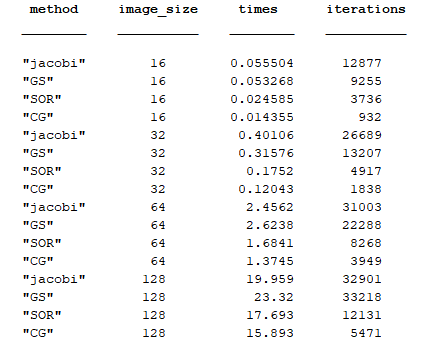

#### And the result denoised images are like:

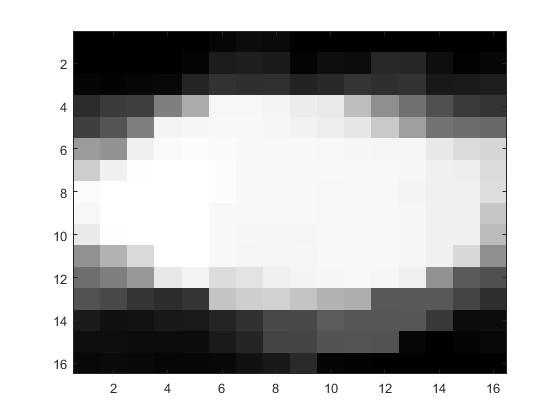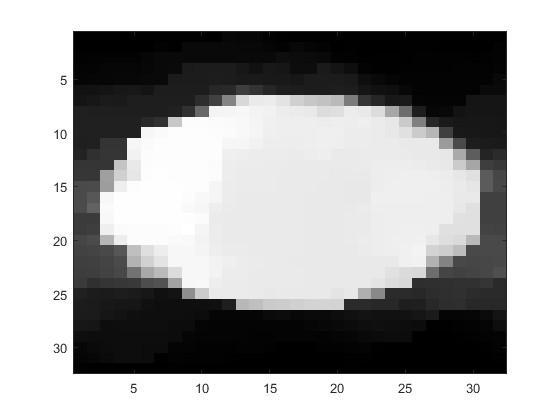

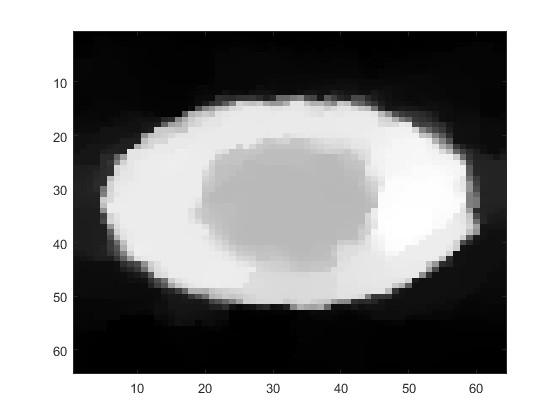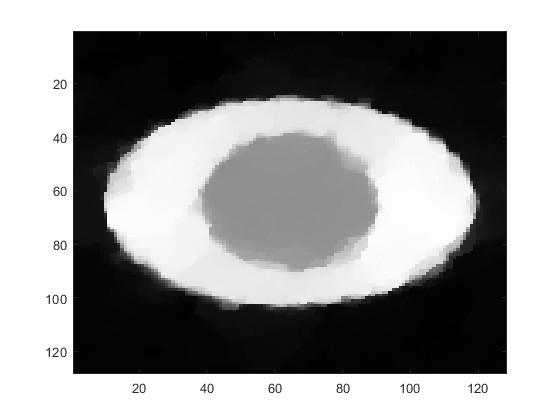

#### Comments:

From the table, we see that the running costs of four methods show a clear pattern with respect to four different image sizes. The time cost of Jacobi is the highest, while the CG method is the lowest. SOR method has a considerably lower cost and iterations than Jacobi and GS, and CG is much lower than all three. However, with the image size increases, we see that the GS method becomes more and more inefficient. When the image size is 128, the cost of running GS and iterations are actually higher than Jacobi. 